# EVD and SVD (HW07 hints)

Math 3607, Autumn 2021

Tae Eun Kim.3562

clear, clf

## Visualizing Spectra

Define a $64\times64$ Toeplitz matrix using

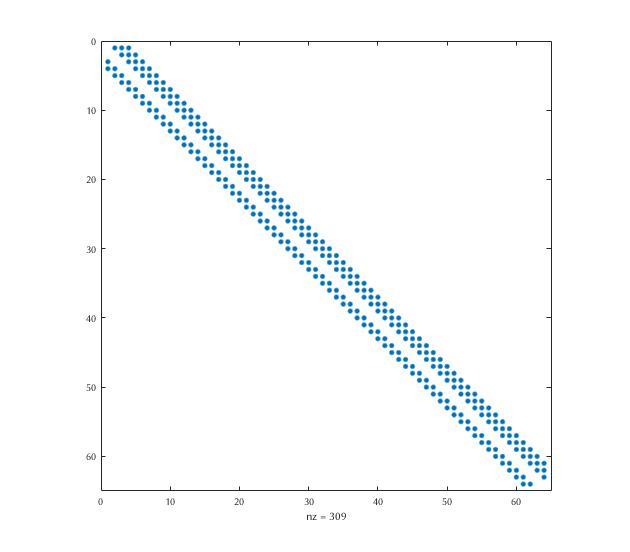

z = zeros(1,60);
A = toeplitz([0,0,-4,-2i,z], [0,2i,-1,2,z]);
spy(A)

(a) Plot the eigenvalues of `A` as red dots in the complex plane. (Set '`MarkerSize`' to be 3.)

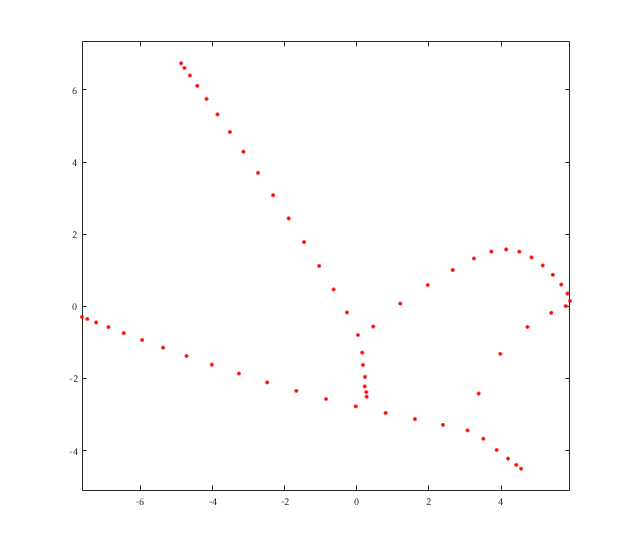

lambda = eig(A);
clf
plot(real(lambda), imag(lambda), 'r.', 'MarkerSize', 10)
axis equal

(b) Let $E$ and $F$ be $64 \times 64$ random matrices generated by `randn`. On top of the plot from part (a), plot the eigenvalues of the matrix $A + \varepsilon E + i \varepsilon F$ as blue dots, where $\varepsilon = 10^{-3}$. (Set '`MarkerSize`' to be 1.)

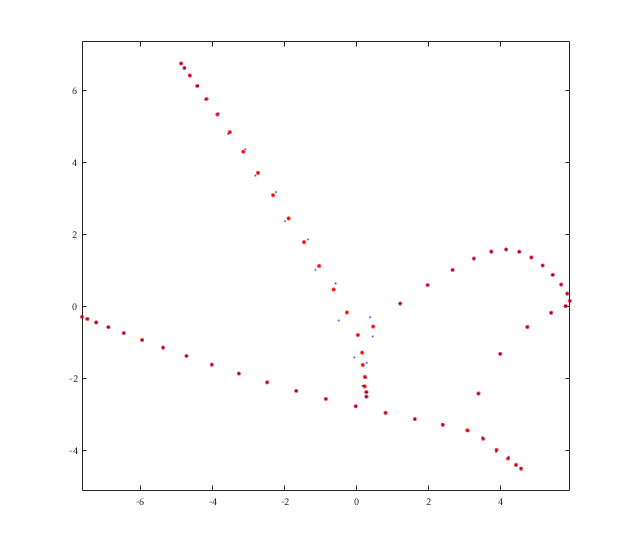

epsilon = 1e-3;
dA = randn(64) + 1i*randn(64);
dA = epsilon*dA/norm(dA);      % ensuring that ||dA||=epsilon
mu = eig(A + dA);
hold on
plot(real(mu), imag(mu), 'b.', 'MarkerSize', 3)

norm(dA)

ans = 1.0000e-03

(c) Repeat part (b) 49 more times (generating a single plot).

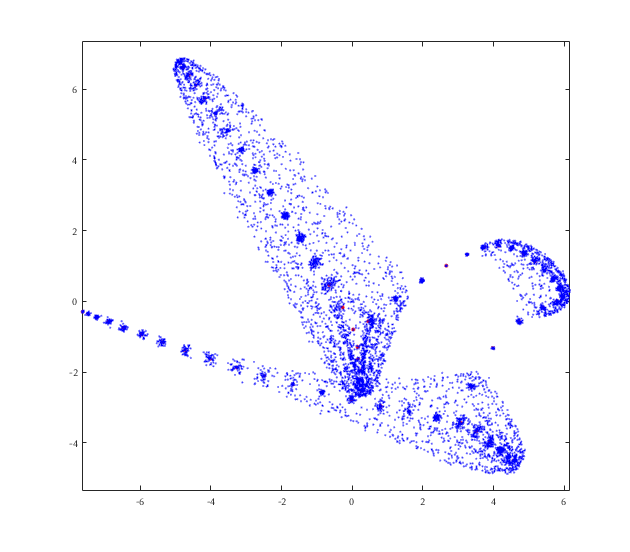

epsilon = 1e-3;
for i = 1:49
    dA = randn(64) + 1i*randn(64);
    dA = epsilon*dA/norm(dA);
    mu = eig(A + dA);
    plot(real(mu), imag(mu), 'b.', 'MarkerSize', 3)
end

(d) (Optional) Compute $\kappa(V)$ for an eigenvector matrix $V$ and relate your picture to the conclusion of the Bauer-Fike theorem.

[V,~] = eig(A);
kappa = cond(V);
kappa*epsilon

## Singular Values of Image Matrices

MATLAB ships with some sample images for trying out ideas. You can get one of these by using

clear

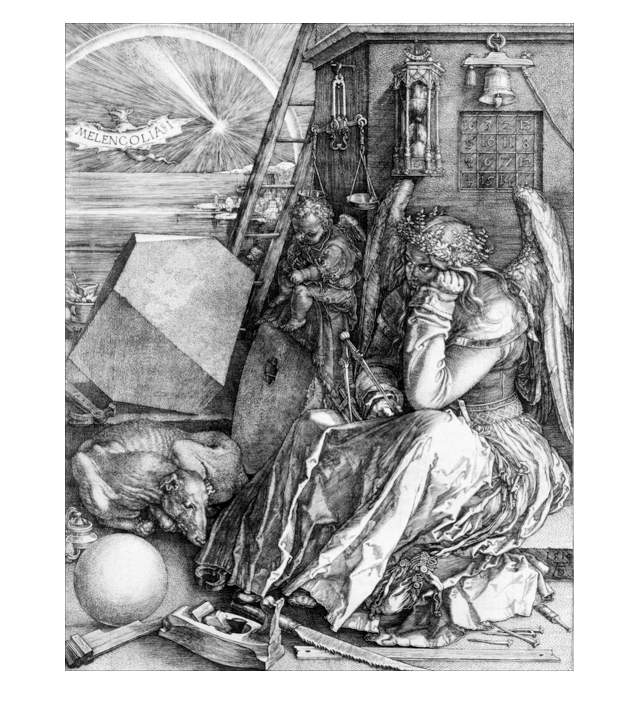

load durer
imshow(X,map)

Make a log-linear plot of the singular values of $X$. (The shape of this graph is surprisingly similar across a wide range of images.)

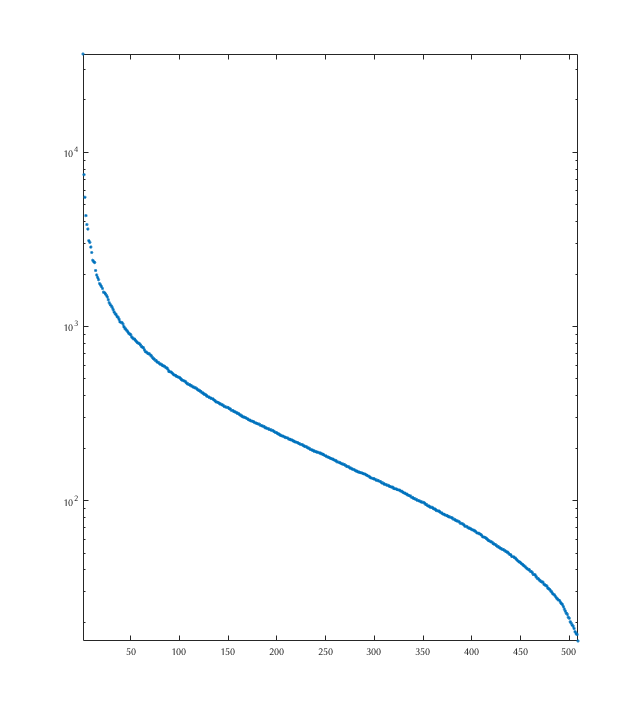

S = svd(X);
semilogy(S, '.'), axis tight